# **Contact Point Analysis on Instrumented Treadmill**

*Motion Capture and COP Measurement Agreement Study*

## **Introduction**

### Context

Accurate foot-ground contact analysis is critical in biomechanics, particularly for gait and running studies. At VUB, we use an instrumented treadmill. However, this was a prototype and very limited information is avalaible. The treadmill is integrated into a Vicon Optical MoCap system.

### Objectives

This study establishes a protocol to find the transformation required to translate the treadmill signals into signals that are compatible with the vicon treadmill plug in (an analog device defined in Nexus that produces the treadmill visualization), and allows to asses the occuracy of the calibrated system.

Error Sources:

- Stick flexion under load (>500N thresholds): ignored because we consider the stick a rigid object

- Time synchronization: We consider it out of scope

- Force plate/marker coordinate system misalignment: reference to procedure callibrate position/ orientation of forceplates (https://github.com/Augment-X/Calibrate_TreadMill)

### Requisits

1. Provide Calibration Guidelines: we consider an opticaly calibrated MoCap system (Vicon guidelines)

2. Make sure analog rate is integer multiple of optical rate

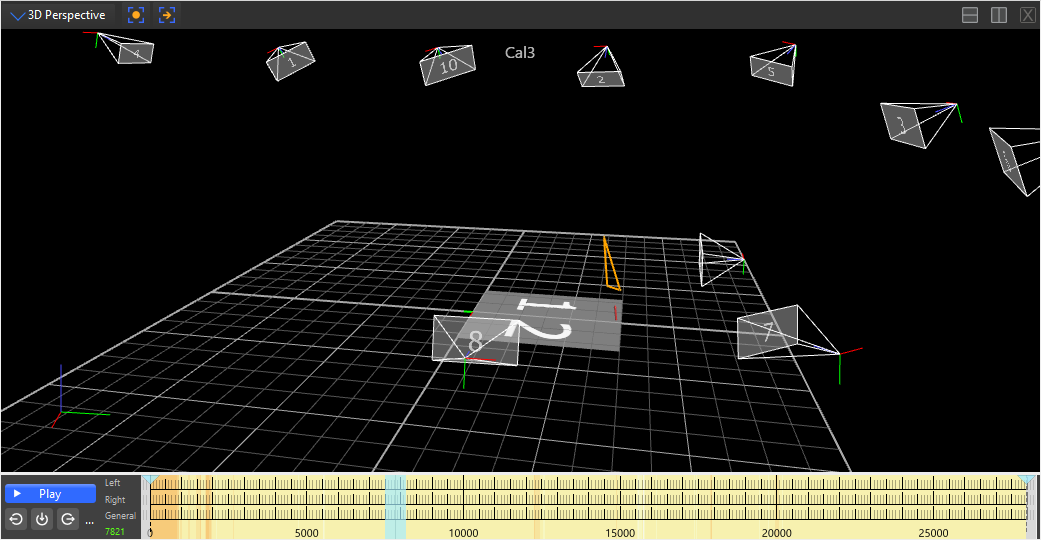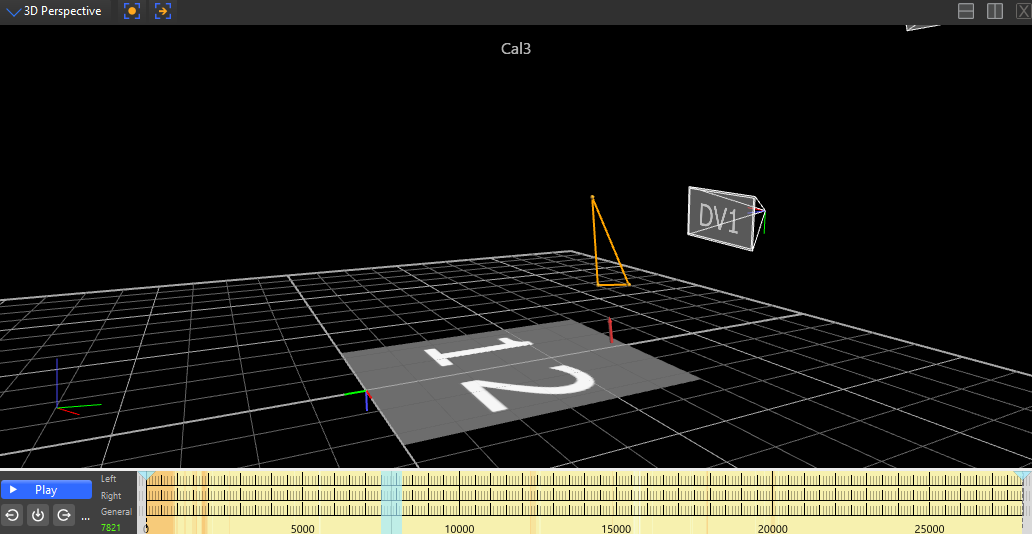

*Figure 1: *Treadmill Bands (1 & 2): Moving surface where contact forces are measured. Marker Triangle: Three reflective markers attached to the calibration stick, used to compute contact point position via geometric calculations.

### Workflow

The calibration code comprises five key phases:

- **Motion Capture Acquisition**: Retrieve 3D marker trajectories (M1-M3) from the calibration stick using Vicon Nexus.

- **Force Plate Data Loading**: Import analog force/moment signals (Fz, Mx, My) from synchronized '.c3d' files.

- **Contact Point Estimation**: Calculate the theoretical contact point by projecting the stick’s marker triangle vertically downward based on its known geometry.

- **Center of Pressure (COP) Computation**: Derive the experimental COP from force plate data using: `COP_x = My/Fz; COP_y = −Mx/Fz  `

- **Reference Frame Alignment & Validation**: Spatially align optical and force plate coordinate systems using Procrustes transformation, then quantify residuals.

## **Marker Trajectory Acquisition**

We use the 'ViconNexus()' API to extract the trajectories of the markers attached to the calibration stick.

% Connect to Vicon Nexus
vicon = ViconNexus();

% Get marker names
Markers = vicon.GetMarkerNames('treadmillCalibrationWand');
n = length(Markers);

% Initialize trajectory variables
trajX = cell(1,n);
trajY = cell(1,n);
trajZ = cell(1,n);

% Acquire frame-by-frame data
for i = 1:n
    [trajX{i}, trajY{i}, trajZ{i}, ~] = vicon.GetTrajectory('treadmillCalibrationWand', Markers{i});
end

N_marker = length(trajX{1}); %frames number
contact_z = 0;
P_contact = NaN(N_marker,3); %estimated contact point

Key Points:

- Uses 3 Vicon markers (M1, M2, M3) on a rigid 1250 mm stick into wich we've placed the markers

- Sampling rate: Typically 100-200 Hz

### Technical Specification - Motion Capture Markers

The calibration stick is equipped with high-precision pearl reflective markers featuring machined hemispherical surfaces. Each marker is coated with 3M's premium reflective material, providing:

## **Force Data Loading**

Analog force data is read from a '.c3d' file using the 'ezc3dRead' function.

Note: Make sure to have the correct path to extract de wanted files.

We extract the vertical force (Fz) and the necessary moments (Mx, My) for COP calculation.

% Read C3D file
acq = ezc3dRead('C:/Users/NS000100/Desktop/Treadmill_callib_files/TreadMill/Cal3.c3d');

% Extract analog data
analog_data = acq.data.analogs;
labels = acq.parameters.ANALOG.LABELS.DATA;

% Identify relevant channels
fz_s = find(strcmp(labels, 'Force.Fz1'));
mx_s = find(strcmp(labels, 'Moment.Mx1'));
my_s = find(strcmp(labels, 'Moment.My1'));

% Extract raw signals
Fz = analog_data(:, fz_s);
Mx = analog_data(:, mx_s);
My = analog_data(:, my_s);

## **Resampling and Filtering**

Since marker data and analog data have different sampling rates, we adjust the signal rate accordingly. 

We also filter out frames with low vertical force (considered as invalid contact).

%synchonize force to marker sampling frequency
N_analog = size(analog_data, 1);
ratio = round(N_analog / N_marker);

% Downsample force data
Fz = Fz(1:ratio:end);
Mx = Mx(1:ratio:end);
My = My(1:ratio:end);

%crop to shortest length
min_N = min(length(Fz), N_marker);
Fz = Fz(1:min_N);
Mx = Mx(1:min_N);
My = My(1:min_N);
P_contact = P_contact(1:min_N, :);

% keeping only frames wherer force is above 50N
valide = abs(Fz) > 50;

**Note: Force Threshold & Measurement Considerations**

- The calibration stick may experience measurable deformation when loaded on the branches.

- Normal use: <50N (validation threshold)

- Maximum: sliding of the belt under shear force is not permited

## **Contact Point Estimation**

We estimate the contact point between the tip of the calibration stick and the ground, based on the position of two markers (`M1` and `M3`) placed on the crossbars perpendicular to the vertical stick.

For that we follow these steps:

- Compute the main axis of the wand (vertical direction) using the two markers.

- Apply a lateral correction (with *correction_offset*) and a vertical correction (called *correction*) to the midpoint between the markers, in order to align the estimated center with the true wand axis. This helps eliminate the small circular artifact observed in previous tests.

- Project the corrected center down along the stick’s axis by the full wand length (*stick_length*) to reach the estimated contact point at the tip.

stick_length = 625;       % half of stick length
correction_offset = 40;   % Décalage latéral
correction = -15;        % Décalage vertical (modifiable)

for t = 1:min_N
    if ~valide(t)
        continue;
    end

    M1 = [trajX{1}(t), trajY{1}(t), trajZ{1}(t)];
    M3 = [trajX{3}(t), trajY{3}(t), trajZ{3}(t)];

    % Axe vertical du stick
    wand_axis = M3-M1;
    wand_axis = wand_axis/norm(wand_axis);
    center = (M1+M3)/2;

    % Axe perpendiculaire dans le plan XY pour corriger latéralement
    up = [0,0,-1];
    correction_dir = cross(wand_axis,up);

    % Application des 2 corrections
    corrected_center = center+(correction_offset*correction_dir)+(correction*correction_dir);

    % projection sur la pointe du stick
    P_contact(t,:) = corrected_center-stick_length*wand_axis;
end

## **Center of Pressure (COP) Computation**

The COP is computed from the force and moment values using basic biomechanics formulas.

Invalid frames are ignored in the analysis

COP_x = My ./ Fz;   %Standard formula: COPx = My/Fz
COP_y = -Mx ./ Fz;  %negative sign often necessary

%Remove the invalid frames
COP_x(~valide) = NaN;
COP_y(~valide) = NaN;

valid_points = ~isnan(COP_x) & ~isnan(P_contact(:,1));

% Application of the optimal offset
P1=[COP_x(valid_points), COP_y(valid_points)];
P2=P_contact(valid_points, 1:2);

[d, Z, transform] = procrustes(P1, P2); %Alignes P2 to P1 using rotation+translation


## **Alignment and Comparison**

To align the COP and the estimated contact point, we calculate the mean position of both and determine the optimal translation. 

We then apply this correction and plot the results.

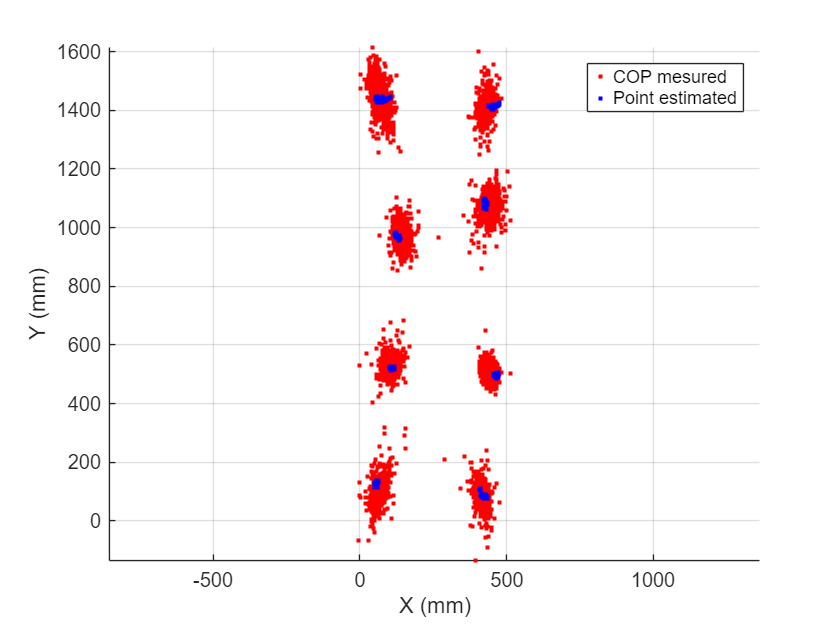

figure;
hold on;

plot(P1(:,1),P1(:,2),'r.','DisplayName','COP mesured');
plot(Z(:,1),Z(:,2),'b.','DisplayName','Point estimated');
xlabel('X(mm)');
ylabel('Y(mm)'); 
legend;
grid on;
axis equal;

%%error
for i = 1:size(Z,1)
    dists=vecnorm(P1 - Z(i,:),2,2);
    min_dist(i)=min(dists);
end
fprintf('Number of valid frames : %d\n', i);

Number of valid frames : 13695


fprintf('Mean error: %.2f mm\n',mean(min_dist));

Mean error: 1.09 mm


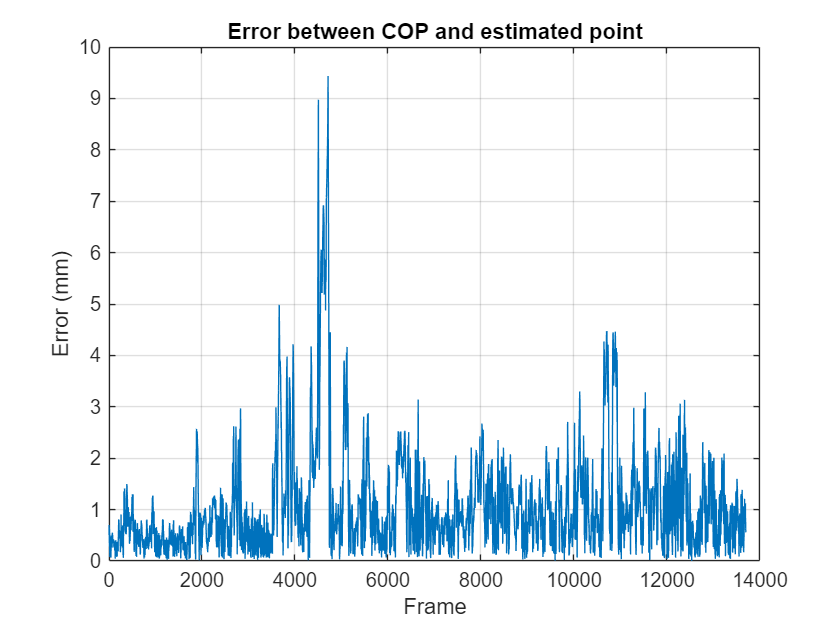

figure(2);
plot(min_dist);
xlabel('Frame');
ylabel('Error (mm)');
title('Error between COP and estimated point');
grid on;